### Modal Analysis of Soft Robot

clear vars; close all; clc;

num_nodes = 1628;
% Import matrices
% Note that damping here is due to Raleigh Damping
% C = alpha * M + beta * K (where alpha = beta = 0.1)
% All matrices extracted from equilibrium point
% M = readmatrix("M.csv");
% K = readmatrix("K.csv");
% C = readmatrix("C.csv");
% H = readmatrix("H.csv");
% u = readmatrix("inputs.csv");

% DAMP = alpha * M + beta * K (where alpha = 2.5, beta = 0.01)
M = readmatrix("M_actual.csv");
K = readmatrix("K_actual.csv");
DAMP = readmatrix("C_actual.csv");
H = readmatrix("H_actual.csv");

z = readmatrix("z.csv").';
u = readmatrix("inputs_actual.csv");

% Recall: format of x is x = (v, q)
% This is the output configuration for figure 8!
vq = readmatrix("vq.csv").';
q = vq(3*num_nodes+1:end, 300:end);

% Build C (output matrix)
output_node = 1354;
C = zeros(3, 3 * num_nodes);
C(1, 3*output_node + 1) = 1;
C(2, 3*output_node + 2) = 1;
C(3, 3*output_node + 3) = 1;

[n,~] = size(M);
fprintf('Completed Matrix import \n');

Completed Matrix import 


## Dynamical system setup and Spectral Analysis

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{D}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})$$


where


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$$


% Using SSMTool functions to do modal analysis
% Disregard nonlinearities for now
fnl = 0;
Emax = 80;
Nmax = 80;

DS = DynamicalSystem();
set(DS,'M',M,'C',DAMP,'K',K,'fnl',fnl);
set(DS.Options,'Emax',Emax,'Nmax',Nmax,'notation','multiindex')
[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 80 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.625096e-01
modal damping ratio for 2 mode is 1.632262e-01
modal damping ratio for 3 mode is 1.649292e-01
modal damping ratio for 4 mode is 1.886772e-01
modal damping ratio for 5 mode is 2.342342e-01
modal damping ratio for 6 mode is 2.392254e-01
modal damping ratio for 7 mode is 2.485037e-01
modal damping ratio for 8 mode is 3.025807e-01
modal damping ratio for 9 mode is 3.056749e-01
modal damping ratio for 10 mode is 3.760413e-01
modal damping ratio for 11 mode is 4.065823e-01
modal damping ratio for 12 mode is 4.383785e-01
modal damping ratio for 13 mode is 4.461984e-01
modal damping ratio for 14 mode is 4.565907e-01
modal damping ratio for 15 mode is 4.718093e-01
modal damping ratio for 16 mode is 4.971546e-01
modal damping rati

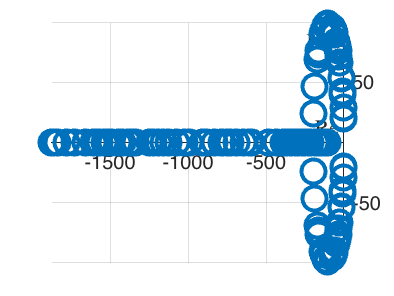


% Plot eigenvalues
% TODO: Simulate FEM and check that system is actually fully damped
plot_eigenvalues_in_complex_plane(D)


% Attempt 1: From Shobhit's code - use to check soln below
% [U, ~, NOT_CONVERGED] = eigs(sparse(K),sparse(M),Emax,'smallestabs');
% wn_check = zeros(Emax,1);
% for j = 1:Emax
%     M_j = U(:,j).'* M * U(:,j);
%     K_j = (U(:,j).'* K * U(:,j));
%     wn_check(j) = sqrt(K_j / M_j);
% end
% wn_check

% ATTEMPT 2: Get natural frequencies and modes (w/o damping)
[PSI, lams] = eigs(M \ K, Nmax, 'smallestabs');
wn = sqrt(diag(lams))

wn =    20.0051
   20.3758
   21.1851
   29.1629
   40.7051
   41.8749
   44.0217
   56.0563
   56.7280
   71.7226



% Convert modes into (x,y,z) format (First two modes here)
mode1 = [PSI(1:3:end, 1) PSI(2:3:end, 1) PSI(3:3:end, 1)].';
mode2 = [PSI(1:3:end, 2) PSI(2:3:end, 2) PSI(3:3:end, 2)].';

**Project input onto dominant modes**

T = 10.01;
dt = 0.01;
N = T / dt;
t_span = linspace(0, T, N+1)

t_span =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


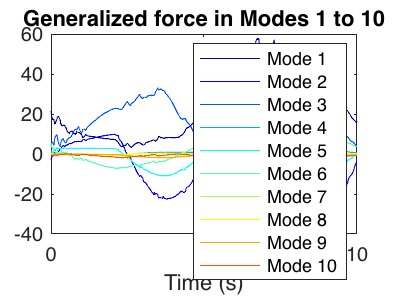

projH = PSI.' * H;
generalizedForces = projH * u.';

% plot first 10 forces associated with dominant modes
figure;
h = plot(t_span, generalizedForces(1:10, :));
legend('Mode 1', 'Mode 2', 'Mode 3', 'Mode 4', 'Mode 5', ...
    'Mode 6', 'Mode 7', 'Mode 8', 'Mode 9', 'Mode 10')
ii = (1:10).';
set(h, {'color'}, num2cell(jet(length(ii)), 2));
title('Generalized force in Modes 1 to 10')
xlabel('Time (s)');

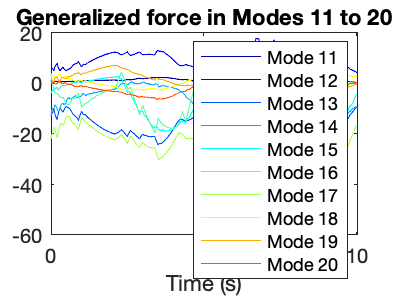


% Next 10 modes
figure;
h = plot(t_span, generalizedForces(11:20, :));
legend('Mode 11', 'Mode 12', 'Mode 13', 'Mode 14', 'Mode 15', ...
    'Mode 16', 'Mode 17', 'Mode 18', 'Mode 19', 'Mode 20')
ii = (1:10).';
set(h, {'color'}, num2cell(jet(length(ii)), 2));
title('Generalized force in Modes 11 to 20')
xlabel('Time (s)');

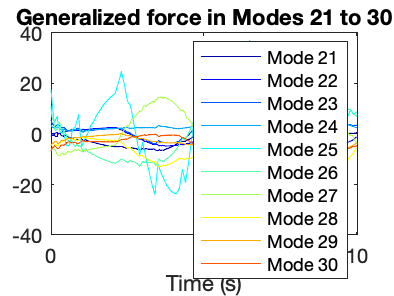


% Next 10 modes
figure;
h = plot(t_span, generalizedForces(21:30, :));
legend('Mode 21', 'Mode 22', 'Mode 23', 'Mode 24', 'Mode 25', ...
    'Mode 26', 'Mode 27', 'Mode 28', 'Mode 29', 'Mode 30')
ii = (1:10).';
set(h, {'color'}, num2cell(jet(length(ii)), 2));
title('Generalized force in Modes 21 to 30')
xlabel('Time (s)');

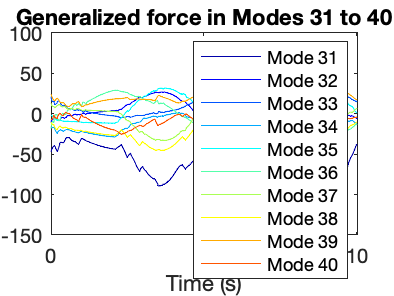


% Next 10 modes
figure;
h = plot(t_span, generalizedForces(31:40, :));
legend('Mode 31', 'Mode 32', 'Mode 33', 'Mode 34', 'Mode 35', ...
    'Mode 36', 'Mode 37', 'Mode 38', 'Mode 39', 'Mode 40')
ii = (1:10).';
set(h, {'color'}, num2cell(jet(length(ii)), 2));
title('Generalized force in Modes 31 to 40')
xlabel('Time (s)');

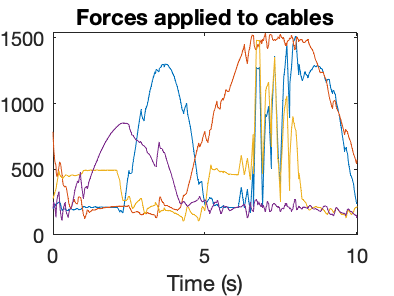


% 10 High frequency modes (TODO: Make this less tedious)
% figure;
% h = plot(t_span, generalizedForces(51:60, :));
% legend('Mode 71', 'Mode 72', 'Mode 73', 'Mode 74', 'Mode 75', ...
%     'Mode 76', 'Mode 77', 'Mode 78', 'Mode 79', 'Mode 80')
% ii = (1:10).';
% set(h, {'color'}, num2cell(jet(length(ii)), 2));
% title('Generalized force in Modes 51 to 60')
% xlabel('Time (s)');

% Random vibration modes
% figure;
% h = plot(t_span, generalizedForces(401:500, :));
% ii = (1:100).';
% set(h, {'color'}, num2cell(jet(length(ii)), 2));
% title('Generized Force in Modes 401 to 500');
% xlabel('Time (s)')
% xlim([0,10]);

% What does actual input look like?
figure;
plot(t_span, u.');
title('Forces applied to cables');
xlabel('Time (s)');

**Project Output onto Dominant Modes**

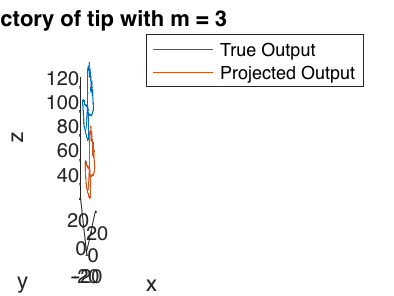

num_modes = 3;
% Form projection matrix
PI = PSI(:,1:num_modes) * PSI(:,1:num_modes).';

% Get projected output
q_proj = PI * q;
z_proj = C * q_proj; % Just the tip

% Reformat actual z (currently (v, q))
z_true = z(4:end, :);

% plot output after projection onto subspace
figure();
plot3(z_true(1, :), z_true(2, :), z_true(3, :))
hold on;
plot3(z_proj(1, :), z_proj(2, :), z_proj(3, :))
legend('True Output', 'Projected Output');
xlabel('x'); ylabel('y'); zlabel('z');
zlim([30, 130]);
str = sprintf('Trajectory of tip with m = %d', num_modes);
title(str)

**Integrate the modes, excited by the inputs!**

% 'ii' is the mode to inspect
ii = 3;
M_bar = PSI.' * M * PSI;
D_bar = PSI.' * DAMP * PSI;
K_bar = PSI.' * K * PSI;

% Get initial conditions of mode ii. Assume v = 0
q_tilde_0 = PSI(:, 1:Nmax).' * q;
mode_ii_0 = [q_tilde_0(ii, 1), 0];

% Input function
u_t = @(t) interp1(t_span, generalizedForces(ii, :), t);

% 1) Run ODE for mode ii
% Takes a very long time because the time scale of the dynamics
% near the origin are small compared to the input, hence adaptive
% time stepping causes very slow integration times (esp for higher modes)
% opts = odeset('RelTol', 1e-1, 'AbsTol',1e-1, 'MaxStep', 0.1);
% ode_func = @(t,x) controlled_ode(t, x, u_t, M_bar(ii,ii), D_bar(ii,ii), K_bar(ii,ii));
% [tsol, xsol] = ode23s(ode_func, t_span, mode_ii_0, opts);

% 2) Or import (Assume tsol is t_span above)
% I save the file since it takes forever to run the integration
filename = sprintf('mode%d.mat', ii);
xsol = load(filename); xsol = xsol.xsol;
tsol = t_span;

**Plot the target mode trajectory**

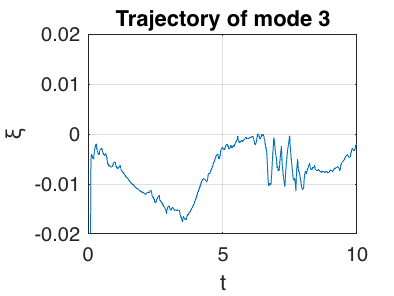

figure();
plot(tsol, xsol(:, 1));
xlabel('t'); ylabel('\xi');
str = sprintf('Trajectory of mode %d', ii);
title(str);
ylim([-0.02, 0.02]);
xlim([0, 10]);
grid on;
ax = gca; % axes handle
ax.YAxis.Exponent = 0;

**Check Spectral Quotient of System**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2];
S.choose_E(masterModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 578
No (near) inner resonances detected in the (truncated) spectrum
sigma_in = 578


**Plot Decay Trajectories**

% This should take values in [1, 2, 3, 12, 13, 23]
modes_initial_condition = 1;
decay_filename = sprintf('mode%d_decay.csv', modes_initial_condition);
mode_decay_trajectory = readmatrix(decay_filename).';
num_modes = 3;

% Take first 3 modes. Recall q = PHI * q_bar (where q_bar is low-dim)
PHI = PSI(:, 1:3);
q_tilde_actual = pinv(PHI) * mode_decay_trajectory;

%% Figure out how trajectory evolves on target modal subspace
M_modal = PHI.' * M * PHI;
D_modal = PHI.' * DAMP * PHI;
K_modal = PHI.' * K * PHI;

% Simulation params
T_modal = 3;
dt_modal = 0.01;
N_modal = T_modal / dt_modal;
t_span_modal = linspace(0, T_modal, N_modal);

% Setup ODE solve (1D only). TODO: NEED TO generalize to higher dim
zero_input = @(t) 0;
% TODO: mode here should only be 1, 2, or 3
% Easy implementation: since decoupled, we can run multiple sims
% for each mode
opts = odeset('RelTol', 1e-1, 'AbsTol',1e-1, 'MaxStep', 0.1);
subspace_trajectories = zeros(N_modal, num_modes);
for jj = 1:3
    % Initial condition starting on the modal subspace
    q_tilde_modal_init = [q_tilde_actual(jj, 1), 0];
    ode_func_modal = @(t,x) controlled_ode(t, x, zero_input, M_modal(jj, jj), D_modal(jj, jj), K_modal(jj, jj));
    [tsol, xsol_modal] = ode23s(ode_func_modal, t_span_modal, q_tilde_modal_init , opts);
    subspace_trajectories(:, jj) = xsol_modal(:,1);
end


**Plot Trajectories and subspace**

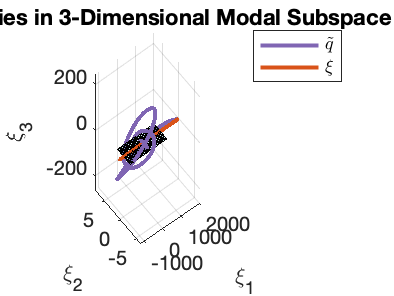

fig = figure();
set(fig,'defaultLegendAutoUpdate','off');

plot3(q_tilde_actual(1,:), q_tilde_actual(2,:), q_tilde_actual(3,:), 'LineWidth',2.0, 'Color', [.5 .4 .7])
hold on;
plot3(subspace_trajectories(:,1), subspace_trajectories(:,2), subspace_trajectories(:,3), 'LineWidth',2.0);
hold on;
xlabel('\xi_1'); ylabel('\xi_2'); zlabel('\xi_3');
title('Trajectories in 3-Dimensional Modal Subspace')
h = legend('$\tilde{q}$', '$\xi$');
h.Interpreter = 'latex';
grid on;

% Mode 1
basis_1 = -1000:100:1000;
basis_2 = -2:2e-1:2;

% Mode 2 and 3
% basis_1 = -1000:100:1000;
% basis_2 = -20:2:20;

% Mode 1/2
% basis_1 = -1000:100:1000;
% basis_2 = -100:10:100;

% Mode 1/3 and 2/3
% basis_1 = -1000:100:1000;
% basis_2 = -1000:100:1000;
% ylim([-50, 50]);

[X,Y] = meshgrid(basis_1, basis_2);
Z = zeros(size(X, 1));
surf(X,Y,Z);
alpha 0.2

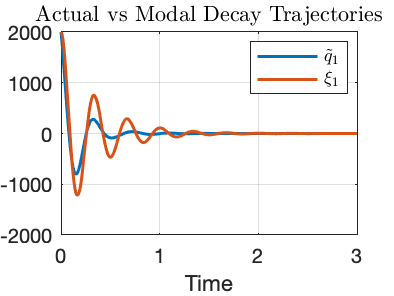


% Compare decay of modes over time
figure;
plot(tsol, q_tilde_actual(1,:), 'LineWidth', 1.5);
hold on;
plot(tsol, subspace_trajectories(:, 1), 'LineWidth', 1.5);
xlabel('Time')
k = title('Actual vs Modal Decay Trajectories');
l = legend('$\tilde{q}_1$', '$\xi_1$');
l.Interpreter = 'latex';
k.Interpreter = 'latex';
grid on;

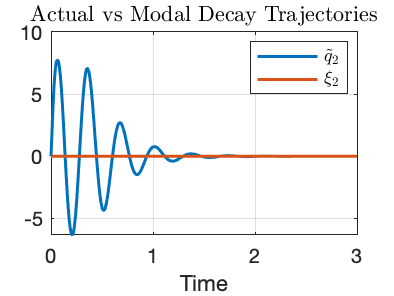


figure;
plot(tsol, q_tilde_actual(2,:), 'LineWidth', 1.5);
hold on;
plot(tsol, subspace_trajectories(:, 2), 'LineWidth', 1.5);
xlabel('Time')
k = title('Actual vs Modal Decay Trajectories');
l = legend('$\tilde{q}_2$', '$\xi_2$');
l.Interpreter = 'latex';
k.Interpreter = 'latex';
grid on;

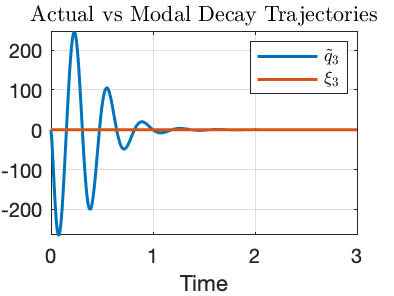


figure;
plot(tsol, q_tilde_actual(3,:), 'LineWidth', 1.5);
hold on;
plot(tsol, subspace_trajectories(:, 3), 'LineWidth', 1.5);
xlabel('Time')
k = title('Actual vs Modal Decay Trajectories');
l = legend('$\tilde{q}_3$', '$\xi_3$');
l.Interpreter = 'latex';
k.Interpreter = 'latex';
grid on;